clear all; clc;
% cd(fileparts(which(mfilename)));  % In a .m file uncomment this
cd(fileparts(matlab.desktop.editor.getActiveFilename)); % In a .mlx file uncomment this

# Example: Mass Spring Damper

Develop a Kalman filter to track the state of the typical Mass Spring Damper. We have an external forze. We use an acceleration sensor.

## 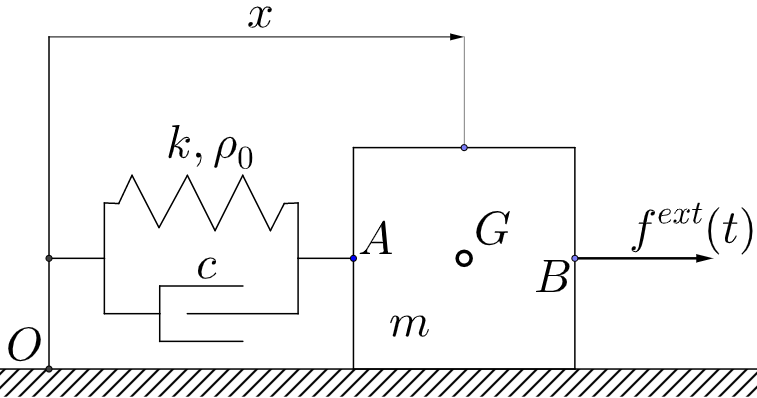

# Solution:

## Parameters and initial state definition

global t t_0 t_end Delta_t
global mu_x Sigma2_x
global u_meas z_meas
global sigma_u_actual sigma_z_actual x_actual x_actual_0 u_actual_func rng_status seed
global x_string u_string z_string
global param

Define actual to function determining the actual input

u_actual_func = @(t) my_u_actual_func(t);

Seed to get repeatable results between runs (particularly important for ML estimation)

seed=1789; rng(seed);
rng_status=rng;

Set initial time $t_0$, sampling frequency $\Delta t$ and final simulation time $t_{end}$

t_0=0;         		    %s
Delta_t=0.005;          %s
t_end=50;               %s

Define model parameters

m=1;          %kg
k=20;         %kg/s^2
rho0=1;       %m
c=0.1;        %kg/s
param=[m k rho0 c Delta_t]'; % as is from main_symbolic_EKF.m

Set deterministic true/actual system Initial state $\mathbf{x}_0^{tr}$

x_0=2;        %m
dx_0=0;       %m/s
q_0=[x_0]';
dq_0=[dx_0]';
x_actual_0=[q_0;dq_0];

Filter Initial state and variance $\mu_{x_0}$, $\sigma_{x_0}^2$, estimated from limits in historical meassurements

sigma_x0=0.5;  % m no idea at all
sigma_dx0=sigma_x0*sqrt(k/m); % m/s no idea at all
sigma_x_0= [sigma_x0,sigma_dx0]';

mu_x_0 = x_actual_0+sigma_x_0;
Sigma2_x_0 = diag(sigma_x_0.^2); % assumed diagonal @ t=t_0

Model equation error variance $\sigma^2_{u_{k}}$ and $\sigma^2_{w_k}$

n_u=size(u_actual_func(t_0),1);
sigma_f_ext=0.01;
sigma_f_ext_spec=0.08;
sigma_u_actual=[sigma_f_ext];
sigma_u=[sigma_f_ext_spec];

Our Euler discretization assumes $\mathbf{q}_{k+1}=\mathbf{q}_{k}+\frac{1}{1!}\dot{\mathbf{q}}_{k}\Delta t$ and $\dot{\mathbf{q}}_{k+1}=\dot{\mathbf{q}}_{k}+\frac{1}{1!}\ddot{\mathbf{q}}(\mathbf{q}_k,\dot{\mathbf{q}}_k,t_k)\Delta t$ and therefore the errors in discterization can be stimated to be of the order of $\frac{1}{2!}\ddot{\mathbf{q}}(\mathbf{q}_k,\dot{\mathbf{q}}_k,t_k)(\Delta t)^2$ and $\frac{1}{2!}\dddot{\mathbf{q}}(\mathbf{q}_k,\dot{\mathbf{q}}_k,t_k)(\Delta t)^2$ at the level of coordinates and generalized velocities respectively.

max_error_discr=[1/2*Delta_t^2,1/2*Delta_t^2];
sigma_discr=max_error_discr';

Parameters for other noise sources in process equation $\mathbf{w}_{k}$.  Process equation error std $\mathbf{\sigma}_{\mathbf{w}_{k}}$.

n_x=size(x_actual_0,1);
sigma_w_x=zeros([n_x,1]);

Sensor equation error std $\mathbf{\sigma}_{\mathbf{z}_{k+1}}$, and input sensor measurement error std $\mathbf{\sigma}_{\mathbf{u}_{k}}$ can be given based on the specification sheet of the sensors used to measure $\mathbf{z}$ and $\mathbf{u}$ and are used to tune the filter (use a better value if your have one available). $\mathbf{\sigma}_{\mathbf{z}_{k+1}}^{tr}$ and $\mathbf{\sigma}_{\mathbf{u}_{k}}^{tr}$ are the ***actual*** values of the error std for the sensors used to measure $\mathbf{z}$ and $\mathbf{u}$.

sigma_accx_actual=0.1;
sigma_accx_spec=0.8;
sigma_z_actual=diag([sigma_accx_actual]);
sigma_z=[sigma_accx_spec];

Parameters for other noise sources in sensor equation $\mathbf{v}_{k+1}$. Sensor equation error std $\mathbf{\sigma}_{\mathbf{v}_{k+1}}$.

n_z=size(sigma_z_actual,1);
sigma_v_x=zeros(n_z,1);

Set variable names for Plotting()

q_string=["x"];
dq_string=["\dot{x}"];
x_string=[q_string;
          dq_string];
u_string=["f^{ext}"];
z_string=["a_x"];

Set variables to datalog

datalogging_string={'t';'x_actual';'mu_x';'u_actual';'u_meas';'z_actual';'z_meas';'sigma_x'};

## Kalman Filter Loop

Begin filtering

fid=fopen('sol.dat','w');

Reset random number generator

rng(rng_status);

Set initial state

t=t_0;
mu_x=mu_x_0;
Sigma2_x=Sigma2_x_0;
sigma_x=sigma_x_0;

x_actual=x_actual_0;

Read

 u_meas=get_u(); z_meas=get_z();

Write

datalogging(fid, datalogging_string);

Filter iteration

for k=1:t_end/Delta_t

Kalman step

    IEKF(sigma_discr, sigma_z, sigma_u,sigma_w_x,sigma_v_x);

Write 

    datalogging(fid, datalogging_string)
end

End filtering

fclose(fid);

## Observability

Linear observability near the end of the simulation

u_meas=get_u(); z_meas=get_z();
f_x_=f_x(mu_x,u_meas,t,param);
h_x_=h_x(mu_x,u_meas,t,param);
 
OB=obsv(f_x_,h_x_)

OB =   -20.0000   -0.1000
  -19.9900   -0.2000


rank(OB)

ans = 2

size(OB) 

ans =      2     2


Nonlinear observability near the end of the simulation

load_datalogging('sol.dat', datalogging_string);

Nonlinear observabilty matrix must be bigger (more rows) than the linear one. So 5 time steps must suffice ( $5 \times 2=10>8$ )

k=length(t_series)-5;

OB=[h_x(x_actual_series(k,:)',u_meas_series(k,:)',t_series(k,:),param)
    h_x(x_actual_series(k+1,:)',u_meas_series(k+1,:)',t_series(k+1,:),param)*f_x(x_actual_series(k+1,:)',u_meas_series(k+1,:)',t_series(k+1,:),param)
    h_x(x_actual_series(k+2,:)',u_meas_series(k+2,:)',t_series(k+2,:),param)*f_x(x_actual_series(k+2,:)',u_meas_series(k+2,:)',t_series(k+2,:),param)*f_x(x_actual_series(k+1,:)',u_meas_series(k+1,:)',t_series(k+1,:),param)
    h_x(x_actual_series(k+3,:)',u_meas_series(k+3,:)',t_series(k+3,:),param)*f_x(x_actual_series(k+3,:)',u_meas_series(k+3,:)',t_series(k+3,:),param)*f_x(x_actual_series(k+2,:)',u_meas_series(k+2,:)',t_series(k+2,:),param)*f_x(x_actual_series(k+1,:)',u_meas_series(k+1,:)',t_series(k+1,:),param)
    h_x(x_actual_series(k+4,:)',u_meas_series(k+4,:)',t_series(k+4,:),param)*f_x(x_actual_series(k+4,:)',u_meas_series(k+4,:)',t_series(k+4,:),param)*f_x(x_actual_series(k+3,:)',u_meas_series(k+3,:)',t_series(k+3,:),param)*f_x(x_actual_series(k+2,:)',u_meas_series(k+2,:)',t_series(k+2,:),param)*f_x(x_actual_series(k+1,:)',u_meas_series(k+1,:)',t_series(k+1,:),param)]

OB =   -20.0000   -0.1000
  -19.9900   -0.2000
  -19.9700   -0.2998
  -19.9400   -0.3995
  -19.9001   -0.4990


rank(OB)

ans = 2

clear *_series

## Real filter error statistics in the limit when $k \longrightarrow \infty$

We compute the sample mean and std for the prediction error. We consider just the last 100 samples, as for a lienar system and filter this error will become statistically stationary after some time. This statistical stationarity can be seeen in the plots. These values are plotted (as horizontal lines) along with the kalman filter predicted std of the state variables, so robustness can be ascertained.

load_datalogging('sol.dat', datalogging_string)
mu_x_error_series=mu_x_series-x_actual_series;
num_samples_statistic=100;
lim_mu_x_error=mu_x_error_series(end-num_samples_statistic:end,:);
lim_mu_x_error_mean=mean(lim_mu_x_error)

lim_mu_x_error_mean =    -0.0163   -0.0455


lim_mu_x_error_std=std(lim_mu_x_error)

lim_mu_x_error_std =     0.0075    0.0528


sqrt_lim_mu_x_error_squared_mean=mean((lim_mu_x_error).^2).^0.5

sqrt_lim_mu_x_error_squared_mean =     0.0179    0.0695


## Plotting

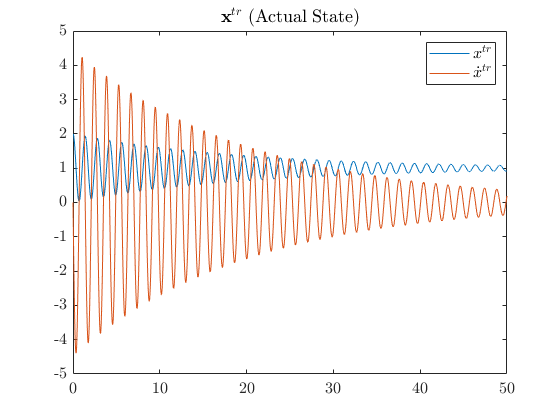

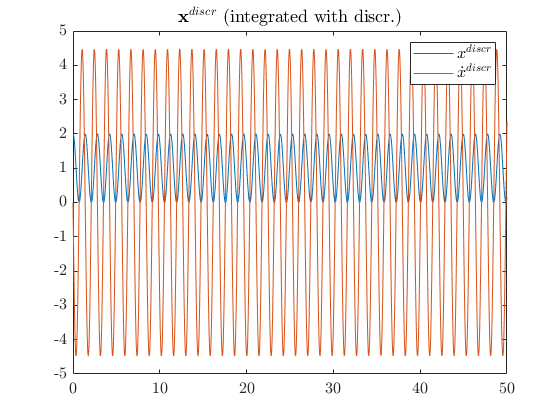

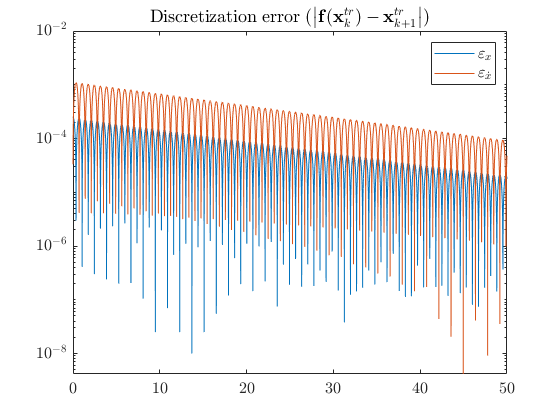

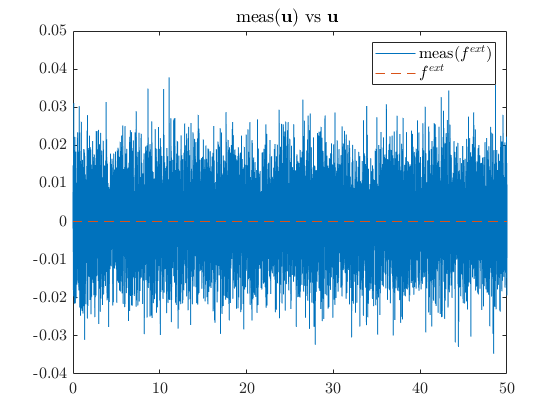

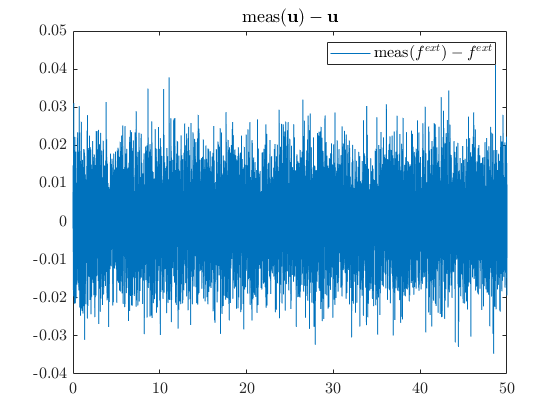

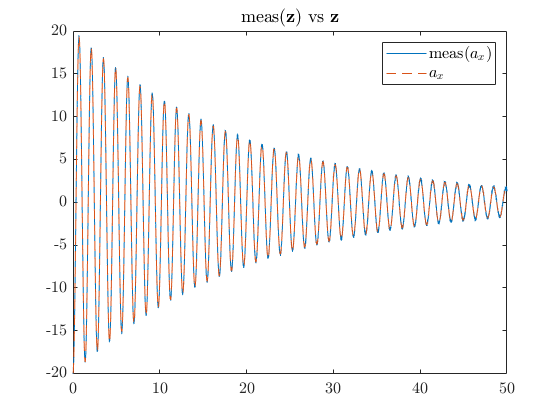

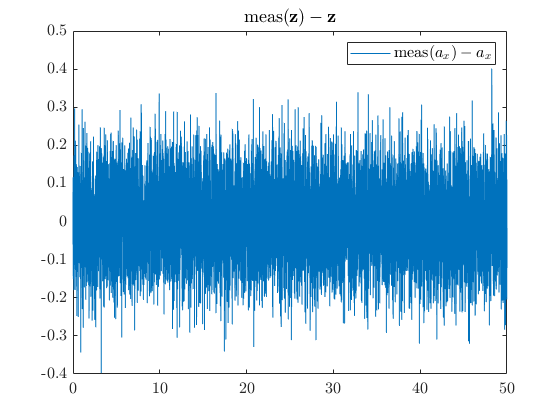

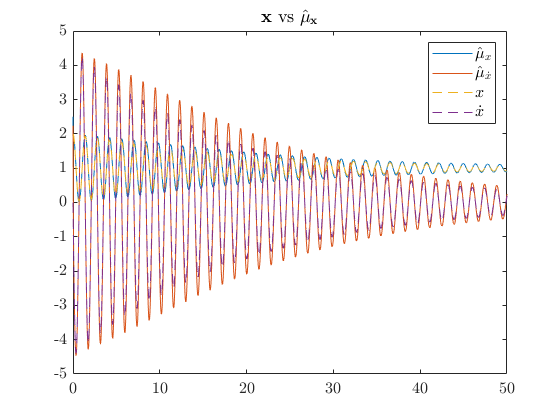

load_datalogging('sol.dat', datalogging_string);
fig_dir=['Information_EKF_',num2str(Delta_t)];
Plotting(fig_dir, datalogging_string);

## Maximum Likelihood (ML) Estimation of Filter Parameters


$$\mathbf{\theta}=[\mathbf{\sigma}_{discr},\mathbf{\sigma}_{\mathbf{z}},\mathbf{\sigma}_{\mathbf{u}}]$$


if not(isfile('ML_opt_1.mat'))
    t=t_0;
    x_actual=x_actual_0;
    theta_=[sigma_discr;sigma_z;sigma_u];
    % function parameters logL_IEKF(sigma_discr,sigma_z,sigma_u,sigma_w_x,sigma_v_x,mu_x_0,sigma_x_0)
    fun = @(theta_) logL_IEKF(theta_(1:2),theta_(3),theta_(4),sigma_w_x,sigma_v_x,mu_x_0,sigma_x_0);
    options = optimset('PlotFcns',@optimplotfval);
    theta_ = fminsearch(fun, theta_,options);
    title('$LogML$','Interpreter','latex');
    xlabel('Iteration','Interpreter','latex');
    ylabel('$LogML$ value','Interpreter','latex');
    sigma_discr=theta_(1:n_x)
    sigma_z=theta_(n_x+1:n_x+n_z)
    sigma_u=theta_(n_x+n_z+1:n_x+n_z+n_u)
    save('ML_opt_1','sigma_discr','sigma_z','sigma_u');
end

## Load previous Maximum Likelihood (ML) Estimation of Filter Parameters

load('ML_opt_1');

## Kalman Filter Loop

Begin filtering

fid=fopen('sol.dat','w');

Reset random number generator

rng(rng_status);

Set initial state

t=t_0;
mu_x=mu_x_0;
Sigma2_x=Sigma2_x_0;
sigma_x=sigma_x_0;

x_actual=x_actual_0;

Read

 u_meas=get_u(); z_meas=get_z();

Write

datalogging(fid, datalogging_string);

Filter iteration

for k=1:t_end/Delta_t

Kalman step

    IEKF(sigma_discr, sigma_z, sigma_u,sigma_w_x,sigma_v_x);

Write 

    datalogging(fid, datalogging_string)
end

End filtering

fclose(fid);

## Real filter error statistics in the limit when $k \longrightarrow \infty$

We compute the sample mean and std for the prediction error. We consider just the last 100 samples, as for a lienar system and filter this error will become statistically stationary after some time. This statistical stationarity can be seeen in the plots. These values are plotted (as horizontal lines) along with the kalman filter predicted std of the state variables, so robustness can be ascertained.

load_datalogging('sol.dat', datalogging_string)
mu_x_error_series=mu_x_series-x_actual_series;
num_samples_statistic=100;
lim_mu_x_error=mu_x_error_series(end-num_samples_statistic:end,:);
lim_mu_x_error_mean=mean(lim_mu_x_error)

lim_mu_x_error_mean =     0.0003   -0.0106


lim_mu_x_error_std=std(lim_mu_x_error)

lim_mu_x_error_std =     0.0013    0.0020


sqrt_lim_mu_x_error_squared_mean=mean((lim_mu_x_error).^2).^0.5

sqrt_lim_mu_x_error_squared_mean =     0.0013    0.0108


## Plotting

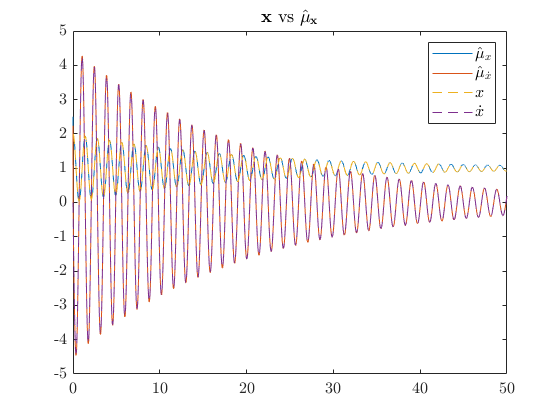

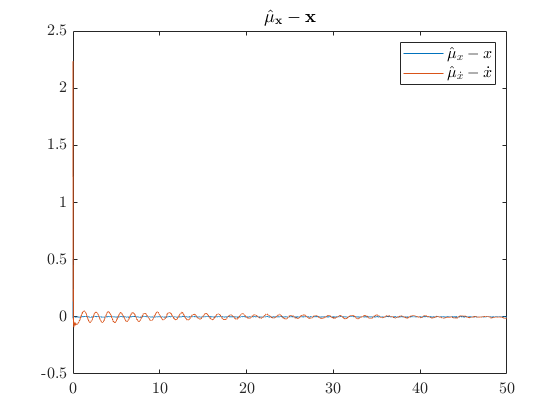

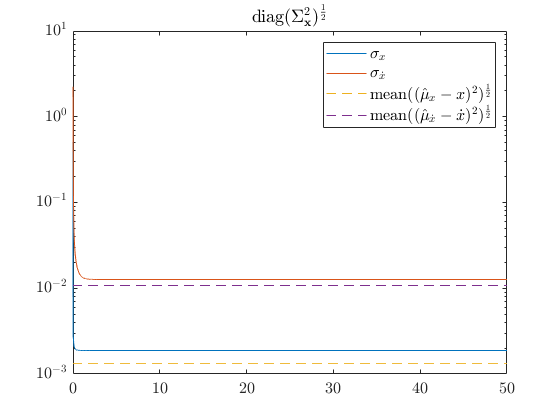

load_datalogging('sol.dat', datalogging_string);
fig_dir=['Information_EKF_',num2str(Delta_t)];
Plotting(fig_dir, datalogging_string);

## Maximum Likelihood (ML) Estimation of Filter Parameters


$$\mathbf{\theta}=[\mathbf{\sigma}_{discr},\mathbf{\sigma}_{\mathbf{z}},\mathbf{\sigma}_{\mathbf{u}},\mathbf{\mu}_{\mathbf{x}_0},\mathbf{\sigma}_{\mathbf{x}_0}]$$


if not(isfile('ML_opt_2.mat'))
    t=t_0;
    x_actual=x_actual_0;
    theta_=[sigma_discr;sigma_z;sigma_u;mu_x_0;sigma_x_0];
    % function parameters: logL_IEKF(sigma_discr,sigma_z,sigma_u,sigma_w_x,sigma_v_x,mu_x_0,sigma_x_0)
    fun = @(theta_) logL_IEKF(theta_(1:n_x),theta_(n_x+1:n_x+n_z),theta_(n_x+n_z+1:n_x+n_z+n_u),sigma_w_x,sigma_v_x,theta_(n_x+n_z+n_u+1:n_x+n_z+n_u+n_x),theta_(n_x+n_z+n_u+n_x+1:n_x+n_z+n_u+n_x+n_x));
    options = optimset('PlotFcns',@optimplotfval);
    theta_ = fminsearch(fun, theta_,options);
    title('$LogML$','Interpreter','latex');
    xlabel('Iteration','Interpreter','latex');
    ylabel('$LogML$ value','Interpreter','latex');
    sigma_discr=theta_(1:n_x)
    sigma_z=theta_(n_x+1:n_x+n_z)
    sigma_u=theta_(n_x+n_z+1:n_x+n_z+n_u)
    mu_x_0=theta_(n_x+n_z+n_u+1:n_x+n_z+n_u+n_x)
    sigma_x_0=theta_(n_x+n_z+n_u+n_x+1:n_x+n_z+n_u+n_x+n_x)
    save('ML_opt_2','sigma_discr','sigma_z','sigma_u','mu_x_0','sigma_x_0');
end

## Load previous Maximum Likelihood (ML) Estimation of Filter Parameters

load('ML_opt_2');

## Kalman Filter Loop

Begin filtering

fid=fopen('sol.dat','w');

Reset random number generator

rng(rng_status);

Set initial state

t=t_0;
mu_x=mu_x_0;
Sigma2_x=Sigma2_x_0;
sigma_x=sigma_x_0;

x_actual=x_actual_0;

Read

 u_meas=get_u(); z_meas=get_z();

Write

datalogging(fid, datalogging_string);

Filter iteration

for k=1:t_end/Delta_t

Kalman step

    IEKF(sigma_discr, sigma_z, sigma_u,sigma_w_x,sigma_v_x);

Write 

    datalogging(fid, datalogging_string)
end

End filtering

fclose(fid);

## Real filter error statistics in the limit when $k \longrightarrow \infty$

We compute the sample mean and std for the prediction error. We consider just the last 100 samples, as for a lienar system and filter this error will become statistically stationary after some time. This statistical stationarity can be seeen in the plots. These values are plotted (as horizontal lines) along with the kalman filter predicted std of the state variables, so robustness can be ascertained.

load_datalogging('sol.dat', datalogging_string)
mu_x_error_series=mu_x_series-x_actual_series;
num_samples_statistic=100;
lim_mu_x_error=mu_x_error_series(end-num_samples_statistic:end,:);
lim_mu_x_error_mean=mean(lim_mu_x_error)

lim_mu_x_error_mean =     0.0005   -0.0018


lim_mu_x_error_std=std(lim_mu_x_error)

lim_mu_x_error_std =     0.0009    0.0075


sqrt_lim_mu_x_error_squared_mean=mean((lim_mu_x_error).^2).^0.5

sqrt_lim_mu_x_error_squared_mean =     0.0010    0.0077


## Plotting

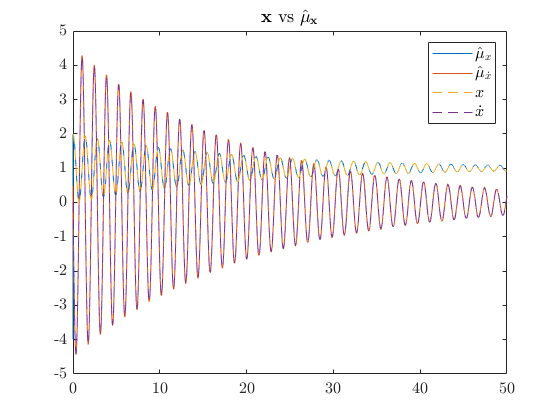

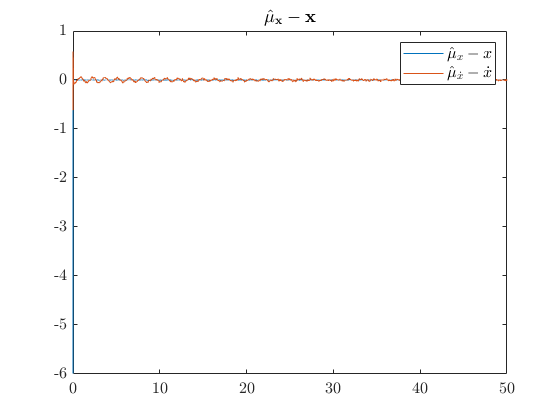

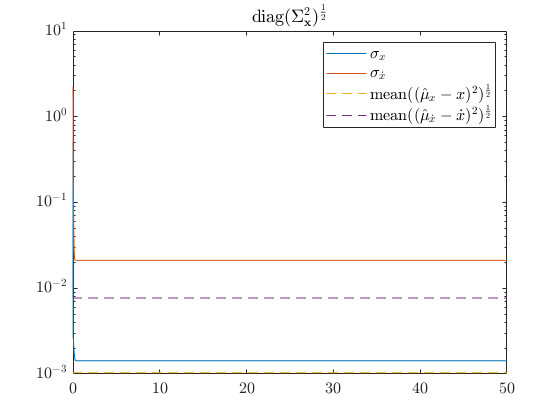

load_datalogging('sol.dat', datalogging_string);
fig_dir=['Information_EKF_',num2str(Delta_t)];
Plotting(fig_dir, datalogging_string);

## Helper functions

function u_actual=my_u_actual_func(t)
u_actual=0.*t;
end